% 本例子采用四个自变量，把所有数据集作为训练集，进行kNN分类
% kNN模型的构建，采用了ExhaustiveSearcher或createns
% 最近邻的搜索采用了knnsearch
% 并且观察了k对kNN分类效果的影响

## Step 1 ===> 加载 Fisher 的鸢尾花数据集。

clear all;
load fisheriris
X = meas;
[n,k] = size(X)

n = 150

k = 4

% X 有 150 个观测值和 4 个自变量。

## Step 2A ===> 使用整个数据集作为训练数据准备一个详尽的最近邻搜索器。

Mdl1 = ExhaustiveSearcher(X)

Mdl1 =   ExhaustiveSearcher with properties:

         Distance: 'euclidean'
    DistParameter: []
                X: [150×4 double]


% Mdl1 是 ExhaustiveSearcher 模型对象，其属性显示在命令行窗口中。
% 该对象包含有关经过训练的算法的信息，例如距离度量。 您可以使用点表示法更改属性值。

## Step 2B ===> 和 Step 2A 等价，实际问题中二者取一个即可

或者，您可以通过使用 createns 并指定 'exhaustive' 作为搜索方法来准备一个详尽的最近邻搜索器。

Mdl2 = createns(X,'NSMethod','exhaustive')

Mdl2 =   ExhaustiveSearcher with properties:

         Distance: 'euclidean'
    DistParameter: []
                X: [150×4 double]


% Mdl2 也是一个 ExhaustiveSearcher 模型对象，它等价于 Mdl1。
% 要为一批查询数据搜索 X 的最近邻居，请将 ExhaustiveSearcher 模型对象和查询数据传递给 knnsearch 或 rangesearch。

## Step 3 ===> 使用Mdl1,对所有X来查询他们在X中的最近邻居

IdxNN1 = knnsearch(Mdl1,X,'K',2);
IdxNN2 = knnsearch(Mdl2,X,'K',2);
[IdxNN1 IdxNN2] % 因为 Mdl2 等价于 Mdl1，IdxNN1和IdxNN2完全相同

ans =      1    18     1    18
     2    35     2    35
     3    48     3    48
     4    48     4    48
     5    38     5    38
     6    19     6    19
     7    48     7    48
     8    40     8    40
     9    39     9    39
    10    35    10    35


## Step 4 ===> 观察k对分类效果的影响

使用四个自变量来分类，不好直接四维画图，而用1维的个数，颜色区分类别进行画图， 纵轴显示k的个数

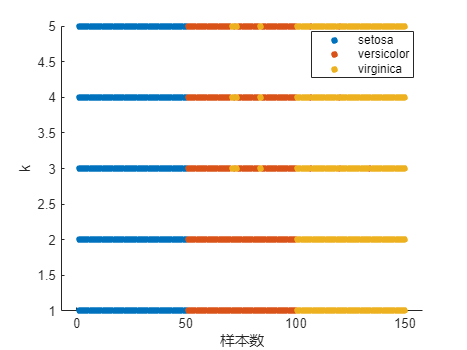

figure;hold on;
gscatter(1:n,ones(n),species)  % 所有类别按1到150画图
for kk=2:5
    IdxNN_kk = knnsearch(Mdl1,X,'K',kk);
    % 给出具体的分类, 存到cc
    cc={};
    for ii=1:n  % n=150个样本
        c1=tabulate(species(IdxNN_kk(ii,:)));
        [a,b]=max(cell2mat(c1(:,2)));  % 投票法找到最大个数对应的类别
        cc=[cc; c1(b,1)]; % 存到cc
    end
    gscatter(1:n,kk*ones(n),cc)
end
xlabel('样本数');
ylabel('k');